*HW4: Configuration Space (Matlab)*

*Arjan Gupta*

*2/52023*

close all; clear; clc;

# Configuration Space Assignment

In this assignment, we will replicate some of the functionality from Prof. Ron Alterovitz's website program. We will create a program consists of a 2D Robotic Manipulator and map the workspace obstacle to the configuration space.

First, we build our robot. with fixed link lengths and DH params.

link1_len = 1;
link2_len = 1;
theta1 = 0;
theta2 = 0;
twolink_robot = rigidBodyTree;
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
dhparams = [link1_len 0 0 theta1
            link2_len 0 0 theta2]; % a alpha d theta
setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
body1.Joint = jnt1;
body2.Joint = jnt2;
addBody(twolink_robot, body1, 'base');
addBody(twolink_robot, body2, 'body1');

Next, we define the starting configuration and show the robot. We also define an obstacle and show it.

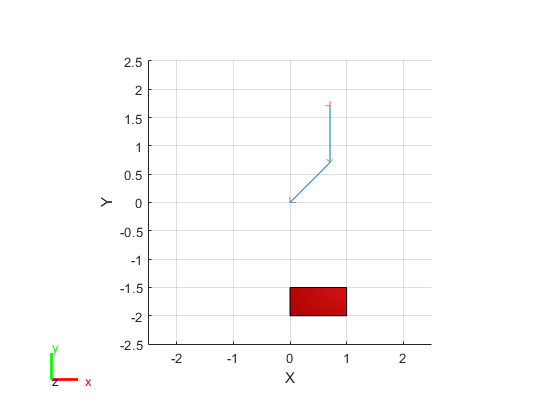

global config 
config = homeConfiguration(twolink_robot);
config(1).JointPosition = deg2rad(45);
config(2).JointPosition = deg2rad(45);
show(twolink_robot, config);
view(2)
ax = gca;
ax.Projection = 'orthographic';
global obstacle1_x
global obstacle1_y
obstacle1_x = [ 0,    0,    1,  1];
obstacle1_y = [-2, -1.5, -1.5, -2];
draw_obstacles(ax);

Next, we start building the configuration space and position sliders for the robot. To do this, we first declare a uifigure.

fig = uifigure('Position',[100 100 500 650]);
grid1 = uigridlayout(fig,[3 1]);
grid1.RowHeight = {370 120 120};

The plot for the cspace is defined using uiaxes. The axes are in degrees, with range 0-360 on each axis.

plot_panel = uipanel(grid1,"Title", "Configuration Space");
ax2 = uiaxes(plot_panel,"XLim",[0 360],"YLim",[0 360]);

Next up, we start defining the scatter plot to show the obstacle being mapped to the configuration space. For mapping the obstacle, we sweep angle theta1 and theta2, and check for end-effector positions that fall in the bounds of the obstacle. If the end-effector is insider the obstacle shape, then a scatter plot marker is added to that location.

global cspace_shape_x
global cspace_shape_y
cspace_shape_x = zeros(1,136);
cspace_shape_y = zeros(1,136);
cspace_shape_x(1) = 45;
cspace_shape_y(1) = 45;
obstacle1_y_max = max(obstacle1_y);
obstacle1_y_min = min(obstacle1_y);
obstacle1_x_max = max(obstacle1_x);
obstacle1_x_min = min(obstacle1_x);
collision_config = homeConfiguration(twolink_robot);
i = 2;
for theta1 = 220:5:360
    collision_config(1).JointPosition = deg2rad(theta1);
    for theta2 = 0:7:360
        collision_config(2).JointPosition = deg2rad(theta2);
        T2 = getTransform(twolink_robot, collision_config, 'body2', 'base');
        tip_x = T2(1,4);
        tip_y = T2(2,4);
        if (tip_y < obstacle1_y_max && tip_y > obstacle1_y_min && tip_x < obstacle1_x_max && tip_x > obstacle1_x_min)
            cspace_shape_x(i) = theta1;
            cspace_shape_y(i) = theta2;
            i = i + 1;
        end
    end
end
plt = scatter(ax2,cspace_shape_x,cspace_shape_y,'r','filled');

Now we use uislider to build the 2 sliders that will control the angular position of each link. Each uislider can also be placed inside a uipanel to make it look nicer.

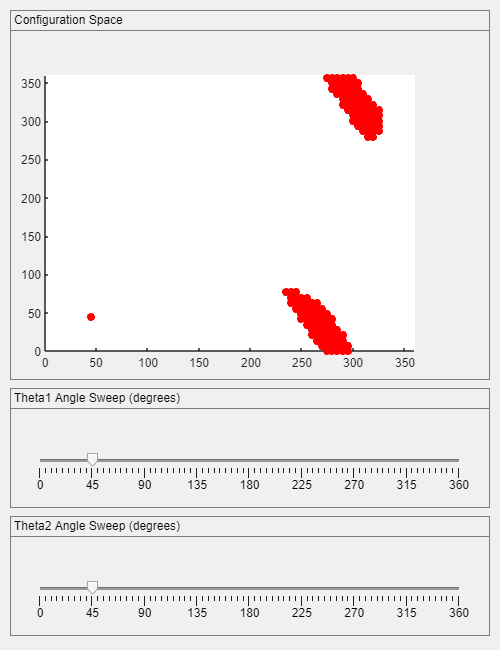

theta1_panel = uipanel(grid1, 'Title', 'Theta1 Angle Sweep (degrees)');
sld1 = uislider(theta1_panel,...
    'Value',45,...
    'Position',[30 70 360 3],...
    'Limits',[0 360],...
    'MajorTicks',[0 45 90 135 180 225 270 315 360],...
    'ValueChangedFcn',@(sld1,event) changeXVal(sld1, plt, twolink_robot));
theta2_panel = uipanel(grid1, 'Title', 'Theta2 Angle Sweep (degrees)');
sld2 = uislider(theta2_panel,...
    'Value',45,...
    'Position',[30 70 360 3],...
    'Limits',[0 360],...
    'MajorTicks',[0 45 90 135 180 225 270 315 360],...
    'ValueChangedFcn',@(sld2,event) changeYVal(sld2, plt, twolink_robot));

**Supporting functions for this Live Script**

The following function defines the callback that is executed everytime the slider for angle theta2 is updated by the user.

function changeYVal(sld, plt, robot)
    global cspace_shape_y
    cspace_shape_y(1) = sld.Value;
    set(plt,'YData',cspace_shape_y);
    global config
    config(2).JointPosition = deg2rad(sld.Value);
    show(robot, config,'PreservePlot',false);
    view(2)
    ax = gca;
    ax.Projection = 'orthographic';
    drawnow;
    draw_obstacles(ax);
end

The following function defines the callback that is executed everytime the slider for angle theta1 is updated by the user.

function changeXVal(sld, plt, robot)
    global cspace_shape_x
    cspace_shape_x(1) = sld.Value;
    set(plt,'XData',cspace_shape_x);
    global config
    config(1).JointPosition = deg2rad(sld.Value);
    show(robot, config,'PreservePlot',false);
    view(2)
    ax = gca;
    ax.Projection = 'orthographic';
    drawnow;
    draw_obstacles(ax);
end

The following function draws the obstacle in the workspace of the robot in this program.

function draw_obstacles(axis)
    global obstacle1_x
    global obstacle1_y
    patch(axis,obstacle1_x,obstacle1_y,'red')
end